# Ecualización del histograma

Un histograma bien distribuido como el del ruido uniforme, contiene por igual valores de todos los tonos de gris. Es por ello que se busca que los pixeles de una imagen se distribuyan tratando de lograr esta forma. 

## **Función de densidad de probabilidad (PDF)**

La **función de densidad de probabilidad (PDF, Probability Density Function)** describe cómo se distribuyen las probabilidades de los posibles valores de una variable aleatoria.

En el caso de las imágenes digitales, la variable aleatoria es la **intensidad de los píxeles**.

Si una imagen tiene $N$ píxeles y $n_k$ de ellos tienen la intensidad $r_k$, la PDF se define como:


$$p(r_k) = \frac{n_k}{N}$$


donde $p(r_k)$ representa la **probabilidad** de que un píxel tomado al azar tenga valor $r_k$.

El **histograma de una imagen** es una representación discreta del número de píxeles en cada nivel de intensidad.

- Si se normaliza dividiendo por el número total de píxeles $N$, el histograma se convierte en una **aproximación de la PDF** de la intensidad.

- Cuanto mayor sea la cantidad de píxeles (y niveles de gris), más el histograma se asemejará a la PDF real.

En resumen:

- **Histograma absoluto** → cuenta de píxeles por nivel.

- **Histograma normalizado** → estimación de la **PDF de intensidades**.

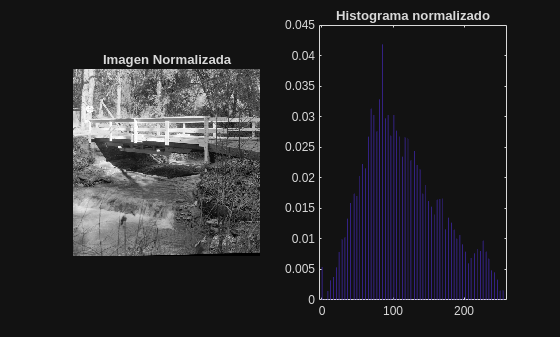

X = double(imread("/home/erit/Desktop/Imagenes/misc/5.2.10.tiff"));
X = mean(X,3);
[M,N] = size(X);

[counts, edges] = histcounts(X(:), 256, 'BinLimits',[0,255]);

% Normalizar para aproximar la PDF
pdf = counts / numel(X);

% Calcular centros de bins
binCenters = (edges(1:end-1) + edges(2:end))/2;

subplot(121)
imshow(X,[]);
title('Imagen Normalizada');

subplot(122)
bar(binCenters,pdf,'hist')
xlim([-4, 260])
title('Histograma normalizado')

## Función de distribución acumulativa

La **función de distribución acumulativa (CDF, por sus siglas en inglés)** describe la probabilidad acumulada de que un píxel tenga una intensidad menor o igual a un valor dado.

En el caso de una imagen digital, se obtiene sumando las frecuencias del histograma hasta cada nivel de intensidad.

Matemáticamente, si $h(r_k)$ es el histograma normalizado (probabilidad de cada nivel de gris $r_k$), la CDF se define como:


$$C(r_k) = \sum_{j=0}^{k} h(r_j)$$


De esta forma, $C(r_k)$ toma valores entre 0 y 1.

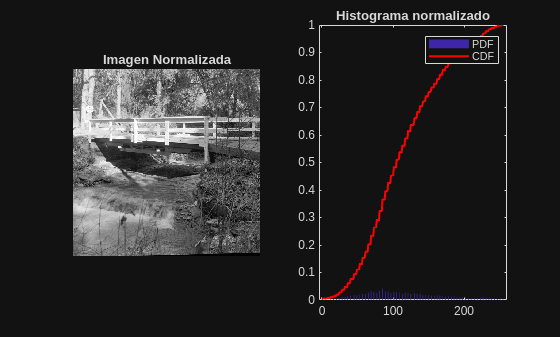

% Calculate the cumulative distribution function (CDF)
cdf = cumsum(pdf);
subplot(122)
hold on;
plot(binCenters, cdf, 'r', 'LineWidth', 1.5);
legend('PDF', 'CDF');
hold off;

La **ecualización del histograma** utiliza la CDF como una función de transformación:

- Cada intensidad de entrada $r_k$ se reemplaza por un nuevo valor proporcional a su CDF acumulada.

- Esto redistribuye los valores de la imagen de modo que el histograma resultante sea más uniforme, mejorando el contraste global.

La transformación se expresa como:


$$s_k = (L-1) \cdot C(r_k)$$


donde $L$ es el número de niveles de intensidad posibles (por ejemplo, 256 en imágenes de 8 bits).

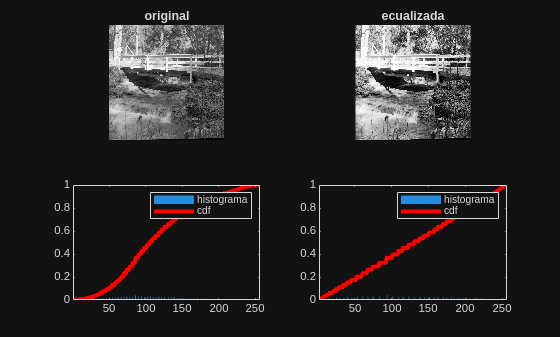

ecualizacion(X);

# Especificación del histograma

La **especificación del histograma** es una técnica del procesamiento digital de imágenes que busca modificar la distribución de niveles de gris de una imagen para que se asemeje a la de otra imagen de referencia. A diferencia de la **ecualización del histograma**, cuyo objetivo es lograr una distribución uniforme, la especificación adapta la segunda imagen para que siga una forma de histograma deseada.

Este procedimiento resulta útil cuando se necesita que dos imágenes tengan condiciones de iluminación o contraste comparables, por ejemplo, en análisis médico o en visión por computadora. En términos prácticos, la imagen a transformar ajusta sus niveles de intensidad de acuerdo con la **función de distribución acumulada (CDF)** de la imagen de referencia, lo que permite que ambas compartan un comportamiento estadístico similar en cuanto al brillo y al contraste.

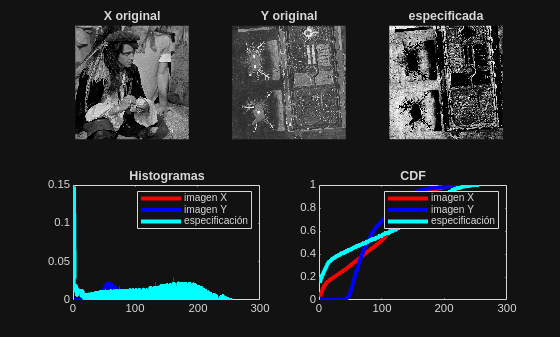

Y = imread("/home/erit/Desktop/Imagenes/misc/5.3.01.tiff");
X = imread("/home/erit/Desktop/Imagenes/misc/5.3.02.tiff");

especificacion(Y,X,256);